**Control M Lab1 report**

- Student Name: Ankai Zhang

- Student ID: 2710818Z


%  your name and student number,
%  a description of the work done in the lab, explaining the tools and methods used,
%  a summary of the results obtained and the observations made, including all plots required in the lab sheet,
%  a discussion of what other methods could be used to improve the results.

**PART 1: SIMULATION**

**1.1 OPEN LOOP SYSTEM**

1.1.1 SYSTEM MODELLING

Rm = 8.4;
kt = 0.042;
km = 0.042;
Jm = 4e-6;
Lm = 1.16;
mh = 0.0106;
rh = 0.0111;
md = 0.053;
rd = 0.0248;
Jeq = Jm + 0.5*mh*rh*rh + 0.5*md*rd*rd;


% Q1.1: Take the Laplace transform of this equation and derive the transfer function
num_g = [kt];
den_g =[Jeq*Rm kt*km 0];
g = tf(num_g,den_g);

% Q1.2: Write down the resulting transfer function in monic form:
a = 1/(Jeq*Rm);
num_g_monic = [kt*a];
den_g_monic = [1 a*kt*km 0];
clear a;
g_monic = tf(num_g_monic, den_g_monic);

% Q1.3: What are the poles and the zeros of the plant transfer function?
z_g = zero(g_monic);
p_g = pole(g_monic);


1.1.3 SIMULATION OF THE PLANT MODEL 

% Q1.4: Describe what you observe. What is the difference between the simulation at 1 rad/s and at 5 rad/s? 
% Does this correspond to what you would expect? [unknown]
% Include plots of the simulation responses in your report.


**plot **

% figure;
% subplot(2,1,1);
% plot(out.ScopeData_Model1_1rad.time,out.ScopeData_Model1_1rad.signals(2).values);
% hold on
% plot(out.ScopeData_Model1_1rad.time,out.ScopeData_Model1_1rad.signals(1).values);
% legend('simulated servo','real servo')
% title('1 rad/s')
% xlabel('Time')
% ylabel('Amplitude')
% hold off
% subplot(2,1,2);
% plot(out.ScopeData_Model1_5rad.time, out.ScopeData_Model1_5rad.signals(2).values);
% hold on
% plot(out.ScopeData_Model1_5rad.time, out.ScopeData_Model1_5rad.signals(1).values);
% legend('simulated servo','real servo')
% title('5 rad/s')
% xlabel('Time')
% ylabel('Amplitude')
% hold off

**1.2 CONTINUOUS-TIME CONTROLLER**

1.2.1.1 LOOP SHAPING FOR D(S)

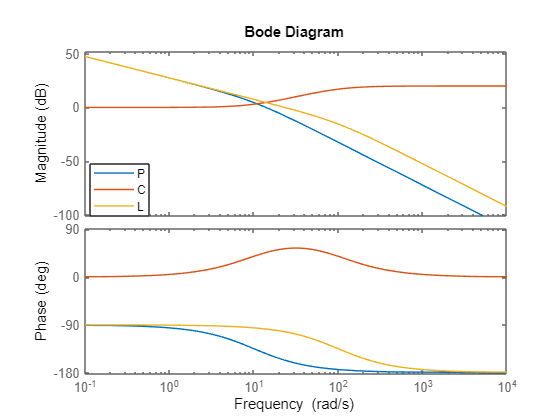

D = tf([10 100],[1 100]);
K = 1;
C = K*D;
P = g_monic;
L = C * P;
% Q1.5: Plot the Bode diagram and include this in your report. Explain the shape of the 
% magnitude and phase of P(s), C(s) and L(s), based on the poles and zeros of the transfer 
% functions. In which way does C(s) affect the loop gain (considering the phase and the 
% magnitude)? [unknown]
figure;
bode(P,C,L);
legend('Position',[0.16113,0.48973,0.10772,0.11962])

z_p = zero(P);
z_c = zero(C);
z_l = zero(L);
p_p = pole(P);
p_c = pole(C);
p_l = pole(L);

% Q1.6: What are the cross-over frequencies for P(s) and L(s)? [unknown]
% What are the gain and phase margins? 

[Gm_P,Pm_P,Wcg_P,Wcp_P] = margin(P);
[Gm_L,Pm_L,Wcg_L,Wcp_L] = margin(L);

% crossover frequencies: L-23.2, P-13.9
% phase margin: L-77, P-35.8
% gain margin: infinity

1.2.1.2 CONTROLLER GAIN K

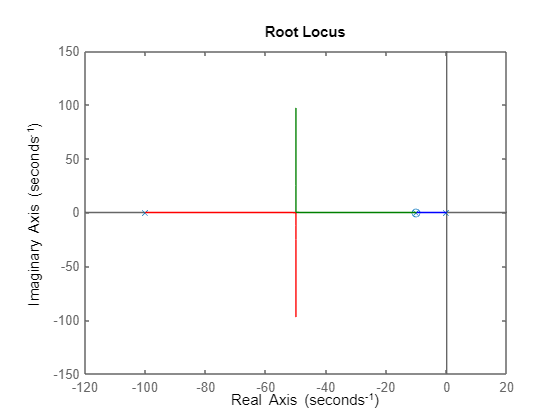

rlocus(L, [0:0.001:5]);

% Q1.7: Using the root-locus plot, find the feedback gains for which
% A. the damping is 1.0 and the frequency of the slowest pole is 5 rad/s,
% B. the overshoot is 5%.
% Note the values for the feedback gains in the table below and determine the locations 
% of all three poles from the root locus plot for these gains. [unknown]

K_A = 0.203;
K_B = 2.2;
p_KA_L = pole(K_A*L);
p_Kb_L = pole(K_B*L);
% A: K = 0.203, 
% B: K = 2.2,
% Pole: -100, -10, 0

% Q1.8 Plot y_s and r against time for the two different gain values. How do the responses for 
% the two gain values differ? [unknown]
% Include the plots of the simulation responses in your report.
% 
% figure;
% subplot(2,1,1);
% plot(out.ScopeData_Model2_KA.time, out.ScopeData_Model2_KA.signals(2).values);
% hold on
% plot(out.ScopeData_Model2_KA.time, out.ScopeData_Model2_KA.signals(1).values);
% legend('y_s','r','u')
% % legend('y_s','r')
% title('K = 0.203')
% xlabel('Time')
% ylabel('Amplitude')
% hold off
% 
% subplot(2,1,2)
% plot(out.ScopeData_Model2_KB.time, out.ScopeData_Model2_KB.signals(2).values);
% hold on
% plot(out.ScopeData_Model2_KB.time, out.ScopeData_Model2_KB.signals(1).values);
% legend('y_s','r','u')
% % legend('y_s','r')
% title('K = 2.2')
% xlabel('Time')
% ylabel('Amplitude')
% hold off

1.2.3 NYQUIST ANALYSIS

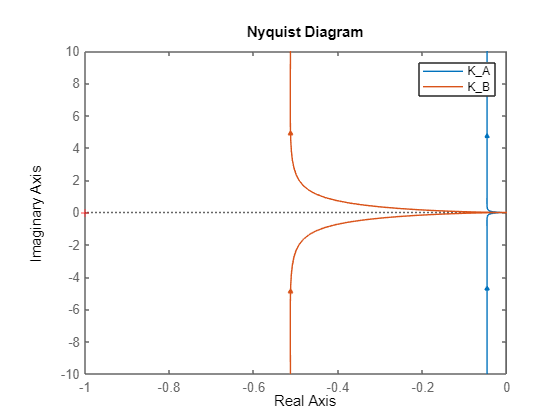

nyquist(K_A*L,K_B*L)
legend('K_A','K_B')

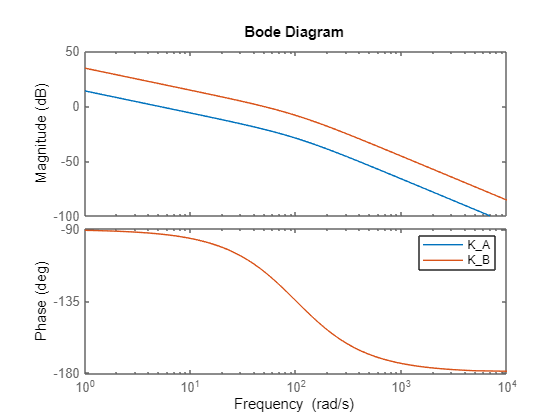


% Q1.9: For the two gain values obtained above, determine the phase margins together with 
% their frequencies and the corresponding delay margin. Enter the values you find in the table 
% below.

% A: Phase margin = 87.3, frequency = 4.83, delay margin = 0.315
% B: Phase margin = 64.7, frequency = 47.4, delay margin = 0.0238



% Q1.10: Generate the Bode plot of the loop gains for the two gain values using the command 
% bode(K_A*L, K_B*L)and include them in your report. Determine the phase margin from
% this plot and compare to those in Table 3.

bode(K_A*L, K_B*L)
legend('K_A','K_B')


% A: 87.3
% B: 64.7

% Q1.11 Include the plots of y_s and r against time for both cases in your report. How does the 
% system behave in both cases? [unknown]
% figure;
% subplot(3,1,1);
% plot(out.ScopeData_Model3_smaller.time, out.ScopeData_Model3_smaller.signals(2).values);
% hold on
% % plot(out.ScopeData_Model3_smaller.time, out.ScopeData_Model3_smaller.signals(1).values);
% % legend('y_s','r','u')
% legend('y_s','r')
% title('K_B = 2.2, t = 0.2(smaller)')
% hold off
% subplot(3,1,2);
% plot(out.ScopeData_Model3_larger.time, out.ScopeData1.signals(2).values);
% hold on
% % plot(out.ScopeData_Model3_larger.time, out.ScopeData_Model3_larger.signals(1).values);
% % legend('y_s','r','u')
% legend('y_s','r')
% title('K_B = 2.2, t = 0.23(smaller)')
% hold off
% subplot(3,1,3);
% plot(out.ScopeData_Model3_larger.time, out.ScopeData_Model3_larger.signals(2).values);
% hold on
% % plot(out.ScopeData_Model3_larger.time, out.ScopeData_Model3_larger.signals(1).values);
% % legend('y_s','r','u')
% legend('y_s','r')
% title('K_B = 2.2, t = 0.3(larger)')
% hold off

1.3 DIGITAL CONTROL

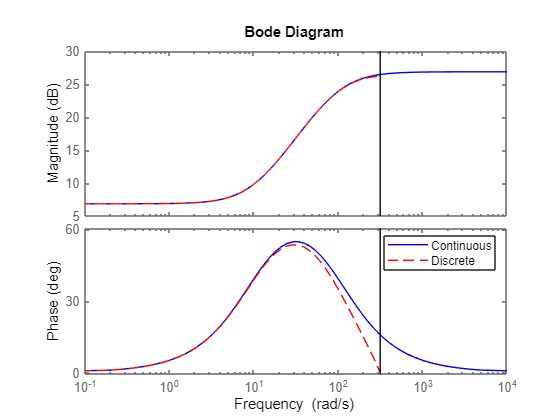

% Q1.12: Given the plant transfer function P, using what you have learnt during the course, and 
% the transforms tables, find the discrete equivalent P(z). Assume a sample time T = 0.01 s.
T = 0.01;
P_zoh = c2d(P, T, 'zoh');


% Q1.13: For the controller gain from B (K_B), find the zeros and poles of the discrete transfer 
% function of the compensator, Dd(z), and its gain (K_d) analytically:
D = tf([10 100],[1 100]);
z_D = zero(D);
p_D = pole(D);
K_B = 2.2;

Dd = c2d(K_B * D, T,'matched');
K_d = 14.61;
Dd = Dd / K_d;

% Q1.14: Use your report to show the Bode diagrams of the continuous and digital 
% compensators using the bode function in MATLAB: bode(K_B*D, 'b', K_d*Dd, 'r--'). 
% Describe the differences/similarities at low and high frequencies. Graphically or by other 
% means, estimate the phase (deg) at 200 rad/s of both continuous and digital compensators.
% [unknown] 为什么高频discrete相位0

bode(K_B*D, 'b', K_d*Dd, 'r--');
legend('Continuous', 'Discrete');

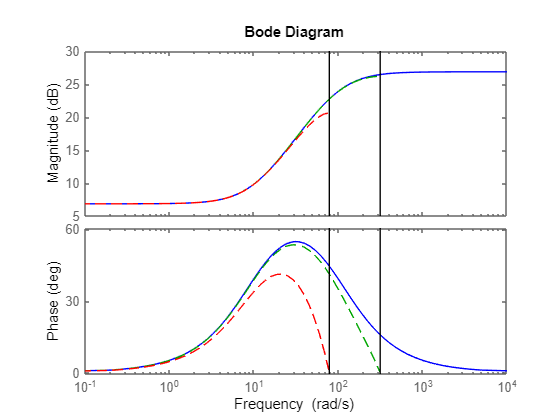


% Q1.15: Use your report to compare the time history of y_s of the simulations of the digital 
% feedback control loop (Model 4) with the analogue (continuous-time) implementation
% (Model 2). How does the performance compare in terms of overshooting and settle time?
% [unknown]

% rlocus(K_d * Dd, [0:0.001:5]);
% figure;
% subplot(2,1,1);
% plot(out.ScopeData_Model4_digital.time, out.ScopeData_Model4_digital.signals(2).values);
% hold on
% % plot(out.ScopeData_Model4_digital.time, out.ScopeData_Model4_digital.signals(1).values);
% % legend('y_s','r','u')
% legend('y_s','r')
% title('Digital T = 0.01')
% hold off
% subplot(2,1,2);
% plot(out.ScopeData_Model4_analogue.time, out.ScopeData_Model4_analogue.signals(2).values);
% hold on
% % plot(out.ScopeData_Model4_analogue.time, out.ScopeData_Model4_analogue.signals(1).values);
% % legend('y_s','r','u')
% legend('y_s','r');
% title('Analogue')
% hold off


% Q1.16: Re-compute the discrete equivalent of the plant P_zoh, the lead compensator Dd and 
% its gain K_d for the new sample time.

T_new = 0.04;
P_zoh_new = c2d(P, T_new, 'zoh');

D = tf([10 100],[1 100]);
z_D = zero(D);
p_D = pole(D);
K_B = 2.2;

Dd_new = c2d(K_B * D, T_new,'matched');
K_d_new = 6.5506;
Dd_new = Dd_new / K_d_new;
bode(K_B*D, 'b', K_d * Dd, 'g--', K_d_new * Dd_new, 'r--');


% Q1.17: Run the digital feedback system (Model 4) again, with the new sample 
% time of 0.04 s. Use your report to plot again the time history of y_s. 
% Is it still stable?

% damp(K_B*D);
% damp(K_d_new * Dd_new);
% nyquist(K_d_new * Dd_new * P_zoh_new);
% rlocus(K_d_new * Dd_new * P_zoh_new);


% figure;
% subplot(3,1,1);
% plot(out.ScopeData_Model4_digital.time, out.ScopeData_Model4_digital.signals(2).values);
% hold on
% % plot(out.ScopeData_Model4_digital.time, out.ScopeData_Model4_digital.signals(1).values);
% % legend('y_s','r','u');
% legend('y_s','r');
% title('Digital T = 0.01')
% hold off
% subplot(3,1,2);
% plot(out.ScopeData_Model4_analogue.time, out.ScopeData_Model4_analogue.signals(2).values);
% hold on
% % plot(out.ScopeData_Model4_analogue.time, out.ScopeData_Model4_analogue.signals(1).values);
% % legend('y_s','r','u')
% legend('y_s','r');
% title('Analogue')
% hold off
% subplot(3,1,3);
% plot(out.ScopeData_Model4_digital_new.time, out.ScopeData_Model4_digital_new.signals(2).values);
% hold on
% % plot(out.ScopeData_Model4_digital_new.time, out.ScopeData_Model4_digital_new.signals(1).values);
% % legend('y_s','r','u');
% legend('y_s','r');
% title('Digital T = 0.04')
% hold off


**PART 2: EVALUATION WITH REALISTIC MODEL **

2.1.1 COMPARISON OF SIMULATION MODEL AND REAL SYSTEM

% Q2.1: Plot the output of the model simulation and the measured output for an input 
% frequency of 1rad/s and 5 rad/s and include them in your report. Note down possible 
% reasons for the differences between them:
% [unknown]

% figure;
% subplot(2,1,1);
% plot(out.ScopeData_Model5_1rad.time,out.ScopeData_Model5_1rad.signals(2).values);
% hold on
% plot(out.ScopeData_Model5_1rad.time,out.ScopeData_Model5_1rad.signals(1).values);
% hold on
% plot(out.ScopeData_Model5_1rad.time,out.ScopeData_Model5_1rad.signals(3).values);
% legend('y_m','u','y_s')
% title('real servo with input at 1 rad/s')
% xlabel('Time');
% ylabel('Amplitude');
% hold off
% subplot(2,1,2);
% plot(out.ScopeData_Model5_5rad.time, out.ScopeData_Model5_5rad.signals(2).values);
% hold on
% plot(out.ScopeData_Model5_5rad.time, out.ScopeData_Model5_5rad.signals(1).values);
% hold on
% plot(out.ScopeData_Model5_5rad.time,out.ScopeData_Model5_5rad.signals(3).values);
% legend('y_m','u','y_s')
% title('real servo with input at 5 rad/s')
% xlabel('Time');
% ylabel('Amplitude');
% hold off

2.2 CONTINUOUS FEEDBACK CONTROL OF THE REAL SERVO SYSTEM

% Q2.2: Plot the output y_s and the reference and include these in 
% your report. Give reasons why the behaviour of the real system is different from 
% that of the simulation with the mathematical model
% Now try using K_B = 0.2 and repeat the experiment. Observe how the behaviour 
% of the closed loop system changes. Relate this to the system analysis you 
% have done in the previous section.

% K_B = 2.23
% figure;
% subplot(2,1,1);
% plot(out.ScopeData_Model6_R_G223.time, out.ScopeData_Model6_R_G223.signals(2).values);
% hold on
% % plot(out.ScopeData_Model6_R_G223.time, out.ScopeData_Model6_R_G223.signals(1).values);
% % legend('y_s','r','u');
% legend('y_s','r');
% title('Realistic Servo, K_B = 2.23, t = 0');
% xlabel('Time');
% ylabel('Amplitude');
% hold off
% subplot(2,1,2);
% plot(out.ScopeData_Model6_S_G223.time, out.ScopeData_Model6_S_G223.signals(2).values);
% hold on
% % plot(out.ScopeData_Model6_S_G223.time, out.ScopeData_Model6_S_G223.signals(1).values);
% % legend('y_s','r','u');
% legend('y_s','r');
% title('Simulation Servo, K_B = 2.23, t = 0');
% xlabel('Time');
% ylabel('Amplitude');
% hold off


% Q2.3: Describe the behaviour of the real servo system for different 
% delays. Include relevant plots in your report. Does it become unstable, like the 
% mathematical model? Try to explain the difference in behaviour between 
% the real servo system and the mathematical model


% K_B = 0.2
% delay margin: 0.315
% change the time delay
% margin 0.32 发散, 之前都稳定

% figure;
% subplot(4,2,1);
% plot(out.ScopeData_Model6_R_G02_t0.time, out.ScopeData_Model6_R_G02_t0.signals(2).values);
% hold on
% % plot(out.ScopeData_Model6_R_G02.time, out.ScopeData_Model6_R_G02.signals(1).values);
% % legend('y_s','r','u');
% legend('y_s','r');
% title('Realistic Servo, K_A = 0.2, t = 0');
% xlabel('Time');
% ylabel('Amplitude');
% hold off
% subplot(4,2,3);
% plot(out.ScopeData_Model6_R_G02_t1.time, out.ScopeData_Model6_R_G02_t1.signals(2).values);
% hold on
% % plot(out.ScopeData_Model6_S_G02.time, out.ScopeData_Model6_S_G02.signals(1).values);
% % legend('y_s','r','u');
% legend('y_s','r');
% title('Realistic Servo, K_A = 0.2, t = 0.15');
% xlabel('Time');
% ylabel('Amplitude');
% hold off
% subplot(4,2,5);
% plot(out.ScopeData_Model6_R_G02_t2.time, out.ScopeData_Model6_R_G02_t2.signals(2).values);
% legend('y_s','r');
% title('Realistic Servo, K_A = 0.2, t = 0.3');
% xlabel('Time');
% ylabel('Amplitude');
% hold off
% subplot(4,2,7);
% plot(out.ScopeData_Model6_R_G02_t3.time, out.ScopeData_Model6_R_G02_t3.signals(2).values);
% legend('y_s','r');
% title('Realistic Servo, K_A = 0.2, t = 0.45');
% xlabel('Time');
% ylabel('Amplitude');
% hold off
% 
% subplot(4,2,2);
% plot(out.ScopeData_Model6_S_G02_t0.time, out.ScopeData_Model6_S_G02_t0.signals(2).values);
% hold on
% legend('y_s','r');
% title('Simulated plant, K_A = 0.2, t = 0');
% xlabel('Time');
% ylabel('Amplitude');
% hold off
% subplot(4,2,4);
% plot(out.ScopeData_Model6_S_G02_t1.time, out.ScopeData_Model6_S_G02_t1.signals(2).values);
% hold on
% legend('y_s','r');
% title('Simulated plant, K_A = 0.2, t = 0.15');
% xlabel('Time');
% ylabel('Amplitude');
% hold off
% subplot(4,2,6);
% plot(out.ScopeData_Model6_S_G02_t2.time, out.ScopeData_Model6_S_G02_t2.signals(2).values);
% legend('y_s','r');
% title('Simulated plant, K_A = 0.2, t = 0.3');
% xlabel('Time');
% ylabel('Amplitude');
% hold off
% subplot(4,2,8);
% plot(out.ScopeData_Model6_S_G02_t3.time, out.ScopeData_Model6_S_G02_t3.signals(2).values);
% legend('y_s','r');
% title('Simulated plant, K_A = 0.2, t = 0.45');
% xlabel('Time');
% ylabel('Amplitude');
% hold off




% Q2.4: Which physical values of the system have changed? Has this affected 
% the behaviour of the closed loop system

% change the servo

% figure;
% subplot(3,1,1);
% plot(out.ScopeData_Model6_R_G02.time, out.ScopeData_Model6_R_G02.signals(2).values);
% hold on
% legend('y_s','r');
% title('Realistic Servo, K_A = 0.2, t = 0');
% xlabel('Time');
% ylabel('Amplitude');
% hold off
% subplot(3,1,2);
% plot(out.ScopeData_Model6_R_G02_nodisk.time, out.ScopeData_Model6_R_G02_nodisk.signals(2).values);
% hold on
% legend('y_s','r');
% title('Realistic Servo without disk, K_A = 0.2, t = 0');
% xlabel('Time');
% ylabel('Amplitude');
% hold off
% subplot(3,1,3);
% plot(out.ScopeData_Model6_S_G02.time, out.ScopeData_Model6_S_G02.signals(2).values);
% hold on
% legend('y_s','r');
% title('Simulated plant, K_A = 0.2, t = 0');
% xlabel('Time');
% ylabel('Amplitude');
% hold off


2.3 REAL-TIME DIGITAL IMPLEMENTATION 

% Q2.5: Use the report to plot and compare the time histories of the 
% continuous (Model 2) and the digital (Model 3) versions of this controller. 
% How does the performance compare in terms of overshooting and settle time?

% figure;
% subplot(2,1,1);
% plot(out.ScopeData_Model7_continuous.time, out.ScopeData_Model7_continuous.signals(2).values);
% hold on
% legend('y_s','r');
% title('Continous');
% xlabel('Time');
% ylabel('Amplitude');
% hold off
% subplot(2,1,2);
% plot(out.ScopeData_Model7_digital.time, out.ScopeData_Model7_digital.signals(2).values);
% hold on
% legend('y_s','r');
% title('Digital T = 0.01');
% xlabel('Time');
% ylabel('Amplitude');
% hold off

% Q2.6: Use the report to plot the time history of the output and 
% discuss how the real plant is affecting the stability. Is it still stable?

% figure;
% subplot(3,1,1);
% plot(out.ScopeData_Model7_continuous.time, out.ScopeData_Model7_continuous.signals(2).values);
% hold on
% legend('y_s','r');
% title('Continous');
% xlabel('Time');
% ylabel('Amplitude');
% hold off
% subplot(3,1,2);
% plot(out.ScopeData_Model7_digital.time, out.ScopeData_Model7_digital.signals(2).values);
% hold on
% legend('y_s','r');
% title('Digital T = 0.01');
% xlabel('Time');
% ylabel('Amplitude');
% hold off
% subplot(3,1,3);
% plot(out.ScopeData_Model7_digital_new.time, out.ScopeData_Model7_digital_new.signals(2).values);
% hold on
% legend('y_s','r');
% title('Digital T = 0.04');
% xlabel('Time');
% ylabel('Amplitude');
% hold off

